# Analisis elevación

import matlab.io.hdfeos.*;
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";
% umbral para ajuste de ventana y datos 
umbral_mapa=0.1;
umbral_datos = 0.09;
anio_inicio=2000;

% Cargar los datos en los arreglos
m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1098 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1098 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


## Generar indices

tam_letra = 12;
% Arreglo donde se almacenara el promedio de NDVI por año
indices_series =zeros(total_pixels,4);
% generar indices 

bp=waitbar(0,'Generando indice de series de tiempo'); 
k=1;
for i=1:ndvi_tam(2)
     for j=1:ndvi_tam(1)
        indices_series(k,1) = k;
        indices_series(k,2) = j;
        indices_series(k,3) = i;
         if sum(~isnan(arr_ndvi_mj(j,i,:)))==0
             indices_series(k,4) = 0;
         else
             indices_series(k,4) = 1;
         end
        k=k+1;
     end
     waitbar(i/ndvi_tam(2),bp,sprintf('Generando indice de series de tiempo (%3.0f%%) ',(i/ndvi_tam(2)*100)));
end
close (bp);




series_tiempo_all = reshape(arr_ndvi_mj, ndvi_tam(1)*ndvi_tam(2) , num_registros)';

serie_tiempo =  series_tiempo_all(:,indices_series(:,4)==1);
sti = indices_series(indices_series(:,4)==1,1);

## Generar mapa de grupos

num_grupos = 2;

grupos = kmeans(serie_tiempo',num_grupos);

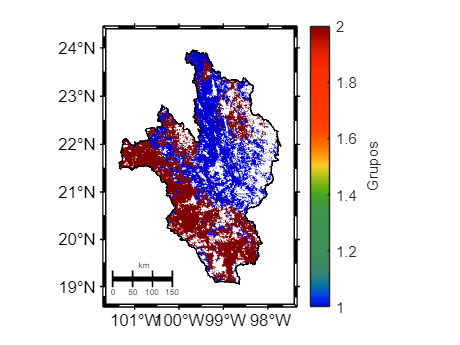


mapa_grupos = NaN(ndvi_tam(1),ndvi_tam(2));

for k=1: length(sti)
    mapa_grupos( indices_series( sti(k),2) ,  indices_series( sti(k),3) )=grupos(k);
end

figure;
mapa_grupos(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_grupos,m_colmap('jet','step',num_grupos),[1 num_grupos],"Grupos");
f_draw_kml(dir_data,"RH26");

 exportgraphics(gca,"img/k-means_"+num_grupos+".png",'Resolution',300) 

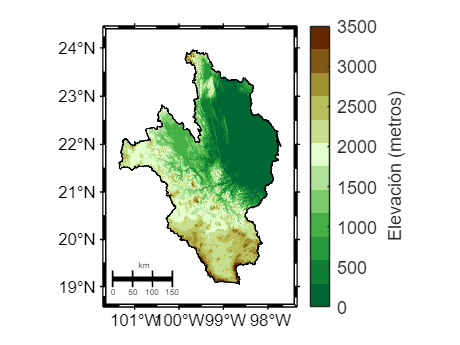

load info_topo.mat

% % colormap de elevacion 
elevation_colormap = [
    0.40 0.16 0.00
    0.51 0.35 0.08
    0.63 0.57 0.20
    0.73 0.75 0.36
    0.78 0.87 0.56
    0.89 1.00 0.80
    0.69 0.89 0.60
    0.48 0.80 0.42
    0.27 0.69 0.27
    0.15 0.60 0.23
    0.06 0.49 0.20
    0.00 0.40 0.20];

elevation_colormap = flipud(elevation_colormap);

topo = f_change_resolution(lat,lon,lat_topo,lon_topo,data_topo);
topo(topo<0)=0;
topo(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,topo,elevation_colormap,[0 3500],"Elevación (metros)");
f_draw_kml(dir_data,"RH26",1,'k',"")
ax = gca;
ax.FontSize=12; 
exportgraphics(gca,"img/ane_elevacion_etopo.png",'Resolution',300); 

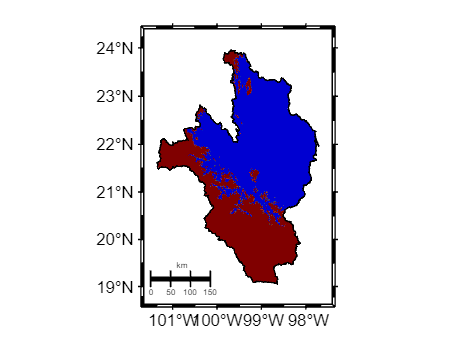


%m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,topo,"México",[],m_colmap('gland',256),"mts");

umbral = 1700;%mejor correlacion = 1691m; CORR: 0.46845
topo_g = topo;

topo_g(topo>umbral) = 2;
topo_g(topo<=umbral) = 1;

f_draw_map(lon_mapa,lat_mapa,lon,lat,topo_g,m_colmap('jet','step',num_grupos),[1 num_grupos]);
f_draw_kml(dir_data,"RH26");

## Correlacion entre elevavion y promedio de ndvi



B = reshape(topo,[],1);
fb = find(B<-1 | B>210000);
B(fb)=nan;
B = B(~isnan(B));

ndvi_prom = f_mean_3dpp(arr_ndvi_mj);
C = reshape(ndvi_prom,[],1);
C(fb)=nan;
C = C(~isnan(C));

R = corrcoef(B,C);
disp("Correlación: "+R(2,1));

Correlación: -0.43075


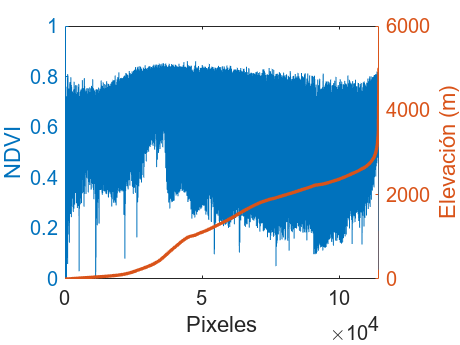


tabla = [B C];
tabla = sortrows(tabla);

ex = 1:length(B);

figure;
yyaxis left 

plot(tabla(:,2));
ylim([0 1]);
xlabel('Pixeles')
ylabel('NDVI')
yyaxis right
plot(ex,tabla(:,1) ,LineWidth=2);
ylabel('Elevación (m)')

tabla = sortrows(tabla,2);
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_corr_ndvi_elevacion.png",'Resolution',300) 

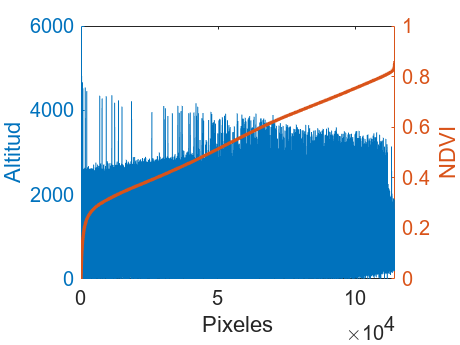


figure;
yyaxis left 
plot(ex,tabla(:,1));
xlabel('Pixeles')
ylabel('Altitud')
yyaxis right
plot(ex,tabla(:,2),'LineWidth',2);
ylabel('NDVI')

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_corr_elevacion_ndvi.png",'Resolution',300) 

## Correlacion entre elevavion y maximo de ndvi



B = reshape(topo,[],1);
fb = find(B<-1 | B>210000);
B(fb)=nan;
B = B(~isnan(B));

ndvi_prom = f_max_3dpp(arr_ndvi_mj);
C = reshape(ndvi_prom,[],1);
C(fb)=nan;
C = C(~isnan(C));

R = corrcoef(B,C);
disp("Correlación: "+R(2,1));

Correlación: -0.41141


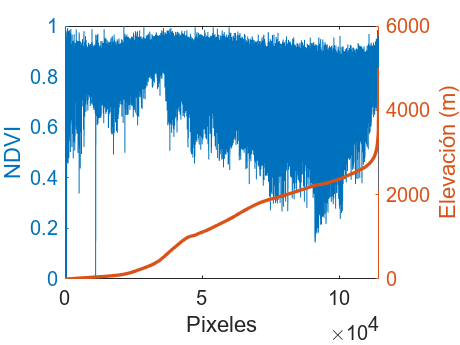


tabla = [B C];
tabla = sortrows(tabla);

ex = 1:length(B);

figure;
yyaxis left 
plot(tabla(:,2));

xlabel('Pixeles')
ylabel('NDVI')
yyaxis right
plot(ex,tabla(:,1) ,LineWidth=2);
ylabel('Elevación (m)')

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_corr_ndvi_elevacion.png",'Resolution',300) 



R = corrcoef(tabla(:,1),tabla(:,2));
disp("Correlación: "+R(2,1));

Correlación: -0.41141


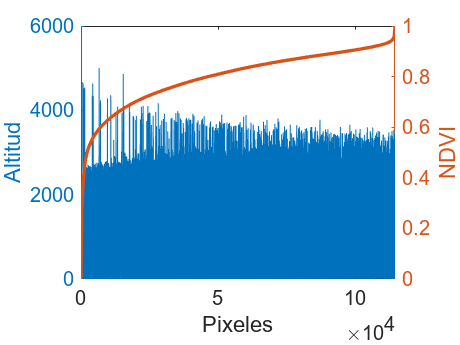



tabla = sortrows(tabla,2);

figure;
yyaxis left 
plot(ex,tabla(:,1));
xlabel('Pixeles')
ylabel('Altitud')
yyaxis right
plot(ex,tabla(:,2),'LineWidth',2);
ylabel('NDVI')

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_corr_elevacion_ndvi.png",'Resolution',300) 


R = corrcoef(tabla(:,1),tabla(:,2));
disp("Correlación: "+R(2,1));

Correlación: -0.41141


## Cuenta pixeles


% % A = reshape(mapa_grupos,[],1);
% % A = A(~isnan(A));

% % g1 = numel( find(A==1&B==1))
% % g2 = numel( find(A==2&B==2))
% % g1_kmeans = numel( find(B==1))
% % g2_kmeans = numel( find(B==2))
% % 
% % C= zeros(total_pixeles,1);
% % C(A==B)=1;
% % 
% % suma = sum(C)
% % p = suma/total_pixeles


% mapa_diff = NaN(size(mapa_grupos));
% 
% mapa_diff(mapa_grupos==topo_g)=2;
% 
% mapa_diff(area_estudio==false)=nan;
% m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_diff,"",[1 num_grupos],m_colmap('jet','step',num_grupos),"");
% %m_dibujar_kml(dir_data,"RH26",1,"k","");



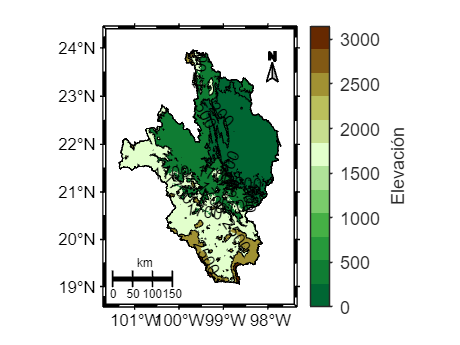


figure;
m_proj('mercator','lon',lon_mapa,'lat',lat_mapa);

colormap(elevation_colormap);   
%m_contourf(lon,lat,topo,[0 125 500 1000 1400 2150 3150],'ShowText','off');
m_contourf(lon,lat,topo,[0 200 500 1700 2500 3150],'ShowText','on');

m_grid('linestyle','none','box','fancy','tickdir','out');
%m_grid('linewi',2,'tickdir','out');

colorbar('eastoutside');
c = colorbar;
c.Label.String = "Elevación";
c.TickDirection = "out";

% % [c1,h1] = contourm(lat,lon,topo,[0 500 1700 2500 3150]);
% % clegendm(c1,h1,0,'m');
% h1=m_line(-98.5,21,'marker','s','color',[0 .5 0],'linest','none','markerfacecolor','w','clip','point');
% h2=m_line(-98.5,22,'marker','o','color','r','linewi',2,'linest','none','markersize',8,'markerfacecolor','w');
% m_grid('linest','none','tickdir','out','box','fancy','fontsize',16);
% legend([h1(1),h2(1)],'Known Hydrothermal vents','Line-P Stations','location','southwest');

% % Regla de escala
m_ruler([.05 .36],.1,3,'fontsize',7)
% %m_northarrow(-101,23.5,.4,'type',2);
% % Estrella del norte 
m_northarrow(-97.9,23.5,.4,'type',2);
f_draw_kml(dir_data,"RH26",1,"k","");
ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_lineas_elevacion_f.png",'Resolution',300) 

## Probar con NDVI solo septiembre

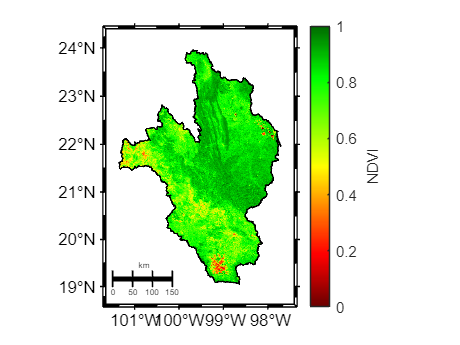

% % NDVI colormap - 256 colors - values 0 to 1 like NASA
ndvi_map_r = [ (33:80)  80*ones(1,79)  (80:-1:0)  zeros(1,48) ]' /80;  % red
ndvi_map_g = flipud( ndvi_map_r );                                     % green
ndvi_map_b = zeros( size( ndvi_map_r ) );                              % blue
ndvi_colormap = [ ndvi_map_r  ndvi_map_g  ndvi_map_b ];

arr_ndvi_mj_max = arr_ndvi_mj;
prom_ndvi_max = f_max_3dpp(arr_ndvi_mj_max);
prom_ndvi_max(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,prom_ndvi_max,ndvi_colormap,[0 1],"NDVI");
f_draw_kml(dir_data,"RH26")
%m_dibujar_otras_areas(dir_data);

exportgraphics(gca,"img/ane_promedio_ndvi_mj_all.png",'Resolution',300) ;


C = reshape(prom_ndvi_max,[],1);
C(fb)=nan;

C = C(~isnan(C));

R = corrcoef(B,C);
disp("Correlación: "+R(2,1));

Correlación: -0.41141


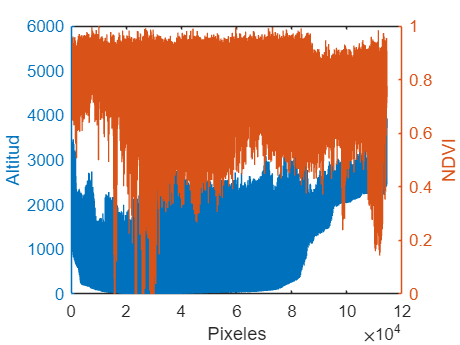


figure;
yyaxis left 
plot(1:length(B),B);
xlabel('Pixeles')
ylabel('Altitud')
yyaxis right
plot(1:length(C),C);
ylabel('NDVI')


mdl = fitlm(B,C)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                         Estimate                    SE                   tStat          pValue
                   _____________________    ____________________    _________________    ______

    (Intercept)         0.86233737579083    0.000518756314219195     1662.31687625581      0   
    x1             -5.00069763429577e-05    3.27318443887801e-07    -152.777752909333      0   


Number of observations: 114564, Error degrees of freedom: 114562
Root Mean Squared Error: 0.103
R-squared: 0.169,  Adjusted R-Squared: 0.169
F-statistic vs. constant model: 2.33e+04, p-value = 0

disp("R2 ord"+mdl.Rsquared.Ordinary);

R2 ord0.16926


disp("R2 adj"+mdl.Rsquared.Adjusted);

R2 adj0.16925


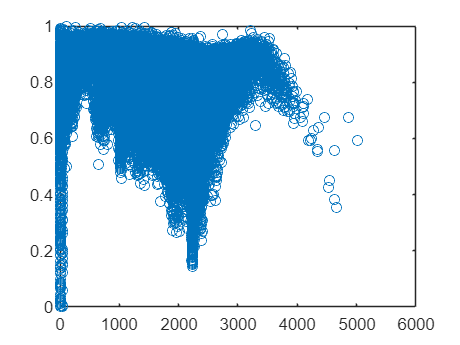


figure;
plot(B,C,'o');

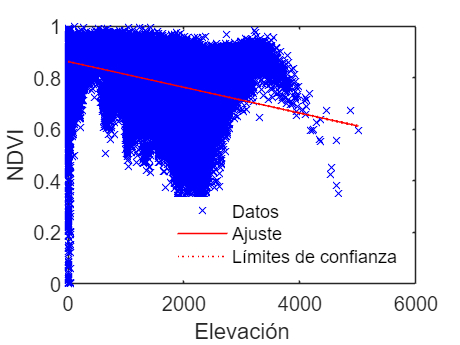


figure;
plot(mdl);
xlabel("Elevación");
ylabel("NDVI");
title("")  
legend('Datos','Ajuste','Límites de confianza',Location="southeast");
legend('boxoff');
ax = gca;
 ax.FontSize=tam_letra; 


B3000 = B(B<3000);
C3000 = C(B<3000);


mdl = fitlm(B3000,C3000)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                         Estimate                    SE                   tStat          pValue
                   _____________________    ____________________    _________________    ______

    (Intercept)        0.865594902001603    0.000517894769686662     1671.37216412768      0   
    x1             -5.38900489930047e-05    3.32649933393261e-07    -162.002284032613      0   


Number of observations: 113365, Error degrees of freedom: 113363
Root Mean Squared Error: 0.102
R-squared: 0.188,  Adjusted R-Squared: 0.188
F-statistic vs. constant model: 2.62e+04, p-value = 0

disp("R2 ord"+mdl.Rsquared.Ordinary);

R2 ord0.18799


disp("R2 adj"+mdl.Rsquared.Adjusted);

R2 adj0.18798


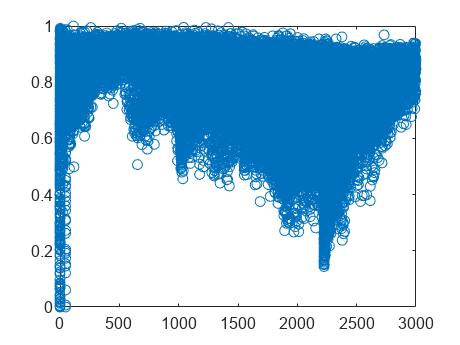


figure;
plot(B3000,C3000,'o');

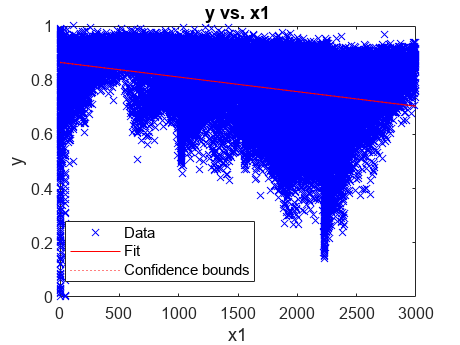


figure;
plot(mdl);

## Buscar correlación agrupando altitudes cada 250m

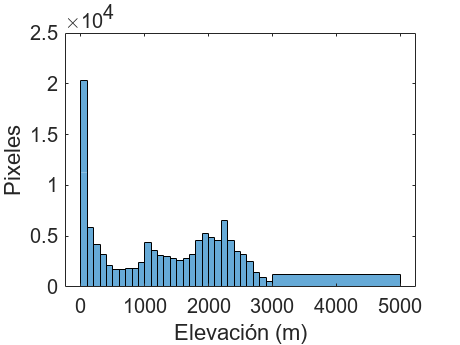

num_bins = 50;
limite = 3000;

figure;
histo_topo = histogram(B,[0:100:3000 5000]);
ax = gca;
ax.FontSize=tam_letra; 
xlabel('Elevación (m)')
ylabel('Pixeles')
exportgraphics(gca,"img/ane_histo_ndvi_ele_100m.png",'Resolution',300) 



histo_topo_val = histo_topo.Values();


ndvi_lf_g250 = zeros(length(histo_topo_val),1);
ndvi_lf_g250_std = zeros(length(histo_topo_val),1);
be = histo_topo.BinEdges(1:length(ndvi_lf_g250)+1);

for i=1:length(ndvi_lf_g250)
    %tmp2 =  ndvi_prom(  topo >= be(i)  & topo <= be(i+1))';
    ndvi_lf_g250(i) = mean( ndvi_prom(  topo >= be(i)  & topo <= be(i+1)) );
    ndvi_lf_g250_std(i) = std( ndvi_prom(  topo >= be(i)  & topo <= be(i+1)) );
end

v = (ndvi_lf_g250-mean(ndvi_lf_g250))./std(ndvi_lf_g250);
h = kstest(v);

if h==0
    disp("Kolmogorov: "+h+" (La serie proviene de distribución normal)");
else
    disp("Kolmogorov: "+h+" (La serie no proviene de distribución normal)");
end

Kolmogorov: false (La serie proviene de distribución normal)


corr_ndvi_histo_topo = corrcoef(ndvi_lf_g250,be(1:length(ndvi_lf_g250)));
disp("Correlacion NDVI-histo topo: "+corr_ndvi_histo_topo(2,1));

Correlacion NDVI-histo topo: -0.59501




mdl = fitlm(ndvi_lf_g250,be(1:length(ndvi_lf_g250)))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                       Estimate                SE                 tStat                 pValue       
                   _________________    ________________    _________________    ____________________

    (Intercept)     8148.34766761402    1672.94997014777      4.8706463510647    3.63396286250794e-05
    x1             -8196.89399112599    2056.03996738456    -3.98673864377892    0.000414728414851673


Number of observations: 31, Error degrees of freedom: 29
Root Mean Squared Error: 743
R-squared: 0.354,  Adjusted R-Squared: 0.332
F-statistic vs. constant model: 15.9, p-value = 0.000415

disp("R2 ord"+mdl.Rsquared.Ordinary);

R2 ord0.35404


disp("R2 adj"+mdl.Rsquared.Adjusted);

R2 adj0.33176



% 
% [~,~,ajuste] = m_reglin(be(1:18),ndvi_lf_g250(1:18)');
% corr_tend_histo_topo = corrcoef(ajuste,be(1:18));
% disp("Corr tendencia NDVI-histo topo: "+corr_tend_histo_topo(2,1));
% 
% [~,~,ajuste2] = m_reglin(be(18:end-1),ndvi_lf_g250(18:end)');
% corr_tend_histo_topo2 = corrcoef(ajuste2,be(18:end-1));
% disp("Corr tendencia NDVI-histo topo: "+corr_tend_histo_topo2(2,1));

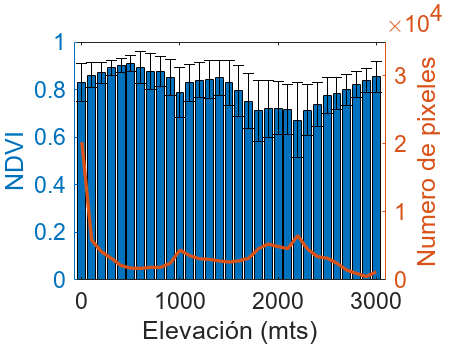


figure;
yyaxis left 
bar(be(1:length(ndvi_lf_g250)),ndvi_lf_g250);
xlabel('Elevación (mts)')
ylabel('NDVI')
ylim([0 1])

hold on
er=errorbar(be(1:length(ndvi_lf_g250)),ndvi_lf_g250,ndvi_lf_g250_std); 
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

% plot(be(1:18),ajuste,"g","LineWidth",2);
% plot(be(18:end-1),ajuste2,"g","LineWidth",2);

hold off

yyaxis right
plot(be(1:length(ndvi_lf_g250)),histo_topo_val,LineWidth=2);
ylabel('Numero de pixeles')
xlim([-80 3100]);
ylim([0 35000]);
ax = gca;
ax.FontSize=14; 
exportgraphics(gca,"img/ane_NDVIxElevacionxNoPixeles.png",'Resolution',300) 

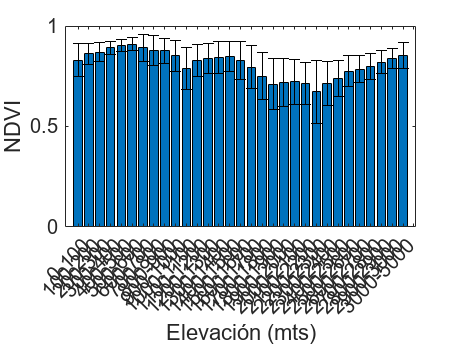


figure;
bar(be(1:length(ndvi_lf_g250)),ndvi_lf_g250);
xlabel('Elevación (mts)')
ylabel('NDVI')
ylim([0 1])


lbl_ejex = string(1: length(ndvi_lf_g250));

for i=1:length(ndvi_lf_g250)
    lbl_ejex (i) = strcat( ""+be(i),"-",""+be(i+1));
end
xticks(0:100:3500)
xticklabels(lbl_ejex)
xtickangle(45);

hold on
er=errorbar(be(1:length(ndvi_lf_g250)),ndvi_lf_g250,ndvi_lf_g250_std); 
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
hold off

ax = gca;
ax.FontSize=tam_letra; 
exportgraphics(gca,"img/ane_NDVIxElevacion.png",'Resolution',300) 

## Pruebas de series de tiempo

h_s = zeros(length(histo_topo_val),1);
h_mwwtest = zeros(length(histo_topo_val),length(histo_topo_val));
h_mwwtest_v = zeros(length(histo_topo_val),length(histo_topo_val));
h_tt2 = zeros(length(histo_topo_val),length(histo_topo_val));
h_kt2 = zeros(length(histo_topo_val),length(histo_topo_val));

% comprobar si provienen de distribuciones normales
for i=1:length(ndvi_lf_g250)
    tmp2 =  ndvi_prom(  topo >= be(i)  & topo <= be(i+1));
    %ndvi_lf_g250(i) = mean( ndvi_prom(  topo >= be(i)  & topo <= be(i+1)) );
    %ndvi_lf_g250_std(i) = std( ndvi_prom(  topo >= be(i)  & topo <= be(i+1)) );

    tmp3 = (tmp2-mean(tmp2))./std( tmp2 );
    h_s(i) = kstest(tmp3);
end

## Mann-Whitney-Wilcoxon test

% to evaluate the difference between unpaired samples.

for i=1:length(ndvi_lf_g250)
    for j=1:length(ndvi_lf_g250)
        m1 =  ndvi_prom(  topo >= be(i)  & topo <= be(i+1))';
        m2 = ndvi_prom(  topo >= be(j)  & topo <= be(j+1))';
        out_mww =  mwwtest(m1,m2);
        if out_mww.p (1) <0.05
            h_mwwtest(i,j) = 1;
        else
            h_mwwtest(i,j) = 0;
        end
        h_mwwtest_v(i,j) = out_mww.p (1);

        h_tt2(i,j) = ttest2(m1,m2);
        h_kt2(i,j) = kstest2(m1,m2);

    end
end

MANN-WHITNEY-WILCOXON TEST
 
                        Group_1      Group_2 
                       _________    _________

    Numerosity             20282        20282
    Sum_of_Rank_W      411369665    411369665
    Mean_Rank            20282.5      20282.5
    Test_variable_U    205679762    205679762

Sample size is large enough to use the normal distribution approximation
 
      Mean             SD                     Z              p_value_one_tail     p_value_two_tails
    _________    _______________    _____________________    _________________    _________________

    205679762    1179222.5572647    -4.24008171247835e-07    0.500000169154787    1.00000033830957 

 
MANN-WHI

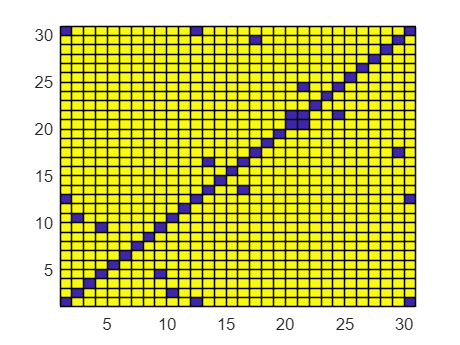

figure;
pcolor( h_mwwtest);

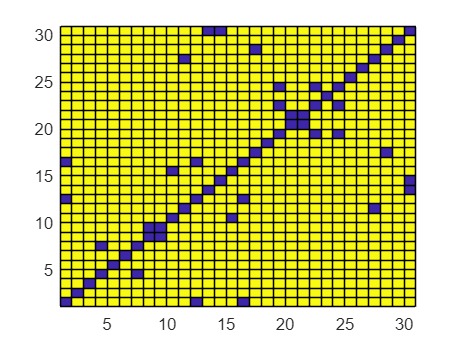


figure;
pcolor(h_tt2); 

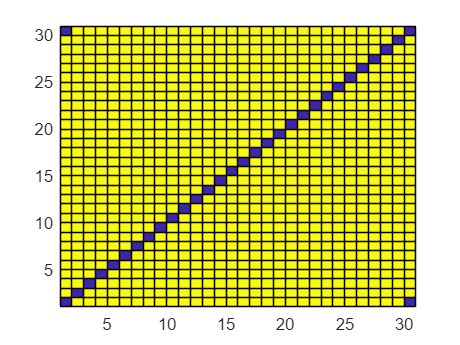


figure;
pcolor(h_kt2); 

% Grafica de caja
bp1 =  ndvi_prom(  topo >= be(1)  & topo <= be(1+1));
bp2 = ndvi_prom(  topo >= be(2)  & topo <= be(2+1));
bp3 = ndvi_prom(  topo >= be(3)  & topo <= be(3+1));
bp4 =  ndvi_prom(  topo >= be(4)  & topo <= be(4+1));
bp5 = ndvi_prom(  topo >= be(5)  & topo <= be(5+1));
bp6 = ndvi_prom(  topo >= be(6)  & topo <= be(6+1));
bp7 = ndvi_prom(  topo >= be(7)  & topo <= be(7+1));
bp8 =  ndvi_prom(  topo >= be(8)  & topo <= be(8+1));
bp9 = ndvi_prom(  topo >= be(9)  & topo <= be(9+1));
bp10 = ndvi_prom(  topo >= be(10)  & topo <= be(10+1));

bp11 =  ndvi_prom(  topo >= be(11)  & topo <= be(11+1));
bp12 = ndvi_prom(  topo >= be(12)  & topo <= be(12+1));
bp13 = ndvi_prom(  topo >= be(13)  & topo <= be(13+1));
bp14 =  ndvi_prom(  topo >= be(14)  & topo <= be(14+1));
bp15 = ndvi_prom(  topo >= be(15)  & topo <= be(15+1));
bp16 = ndvi_prom(  topo >= be(16)  & topo <= be(16+1));
bp17 = ndvi_prom(  topo >= be(17)  & topo <= be(17+1));
bp18 =  ndvi_prom(  topo >= be(18)  & topo <= be(18+1));
bp19 = ndvi_prom(  topo >= be(19)  & topo <= be(19+1));
bp20 = ndvi_prom(  topo >= be(20)  & topo <= be(20+1));

bp21 =  ndvi_prom(  topo >= be(21)  & topo <= be(21+1));
bp22 = ndvi_prom(  topo >= be(22)  & topo <= be(22+1));
bp23 = ndvi_prom(  topo >= be(23)  & topo <= be(23+1));
bp24 =  ndvi_prom(  topo >= be(24)  & topo <= be(24+1));
bp25 = ndvi_prom(  topo >= be(25)  & topo <= be(25+1));
bp26 = ndvi_prom(  topo >= be(26)  & topo <= be(26+1));
bp27 = ndvi_prom(  topo >= be(27)  & topo <= be(27+1));
bp28 =  ndvi_prom(  topo >= be(28)  & topo <= be(28+1));
bp29 = ndvi_prom(  topo >= be(29)  & topo <= be(29+1));
bp30 = ndvi_prom(  topo >= be(30)  & topo <= be(30+1));
bp31 = ndvi_prom(  topo >= be(31)  & topo <= be(31+1));

x = {bp1, bp2, bp3, bp4, bp5, bp6, bp7, bp8, bp9, bp10, ...
    bp11, bp12, bp13, bp14, bp15, bp16, bp17, bp18, bp19, bp20, ...
    bp21, bp22, bp23, bp24, bp25, bp26, bp27, bp28, bp29, bp30, bp31 };

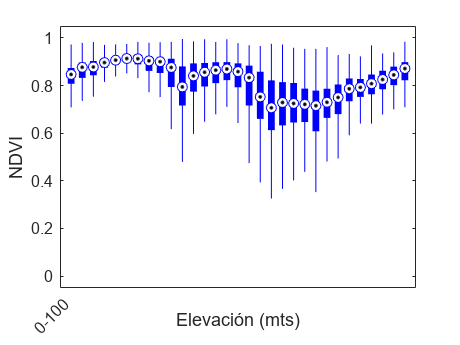


figure;
%%boxplotGroup(x,'PrimaryLabels', lbl_ejex);
% comprobar si provienen de distribuciones normales

% % x = cell(1,10);
% % 
% % for i=i:10
% %     tmp2 =  ndvi_prom(  topo >= be(i)  & topo <= be(i+1));
% %     x(i) = {tmp2};
% % end
% % figure;
 boxplotGroup(x,'symbol', '','PlotStyle','Compact');
xlabel('Elevación (mts)');
ylabel('NDVI');

xticks(0:100:3500)
 xticklabels(lbl_ejex)
xtickangle(45);

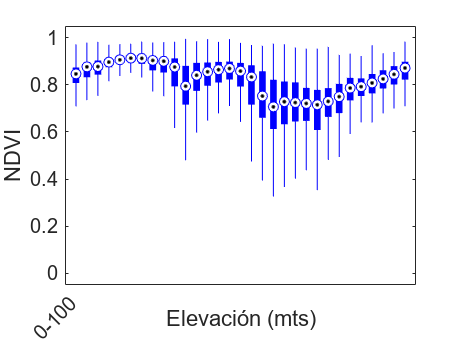


ax = gca;
ax.FontSize=tam_letra; 

exportgraphics(gca,"img/ane_NDVIxElevacionxGrupos.png",'Resolution',300) 

